#  Statistical Modeling Textbook: Linear Regression Model 

##  Statistical Modeling for Data Analysis #2 Theory (2) 

clear;
close all;
load tbl.mat;

###  2. How to choose a model? 

A : 

"Is linear regression just a straight line? With spreadsheet software, you can approximate it with a quadratic function." 

"Can't MATLAB approximate curves?" 

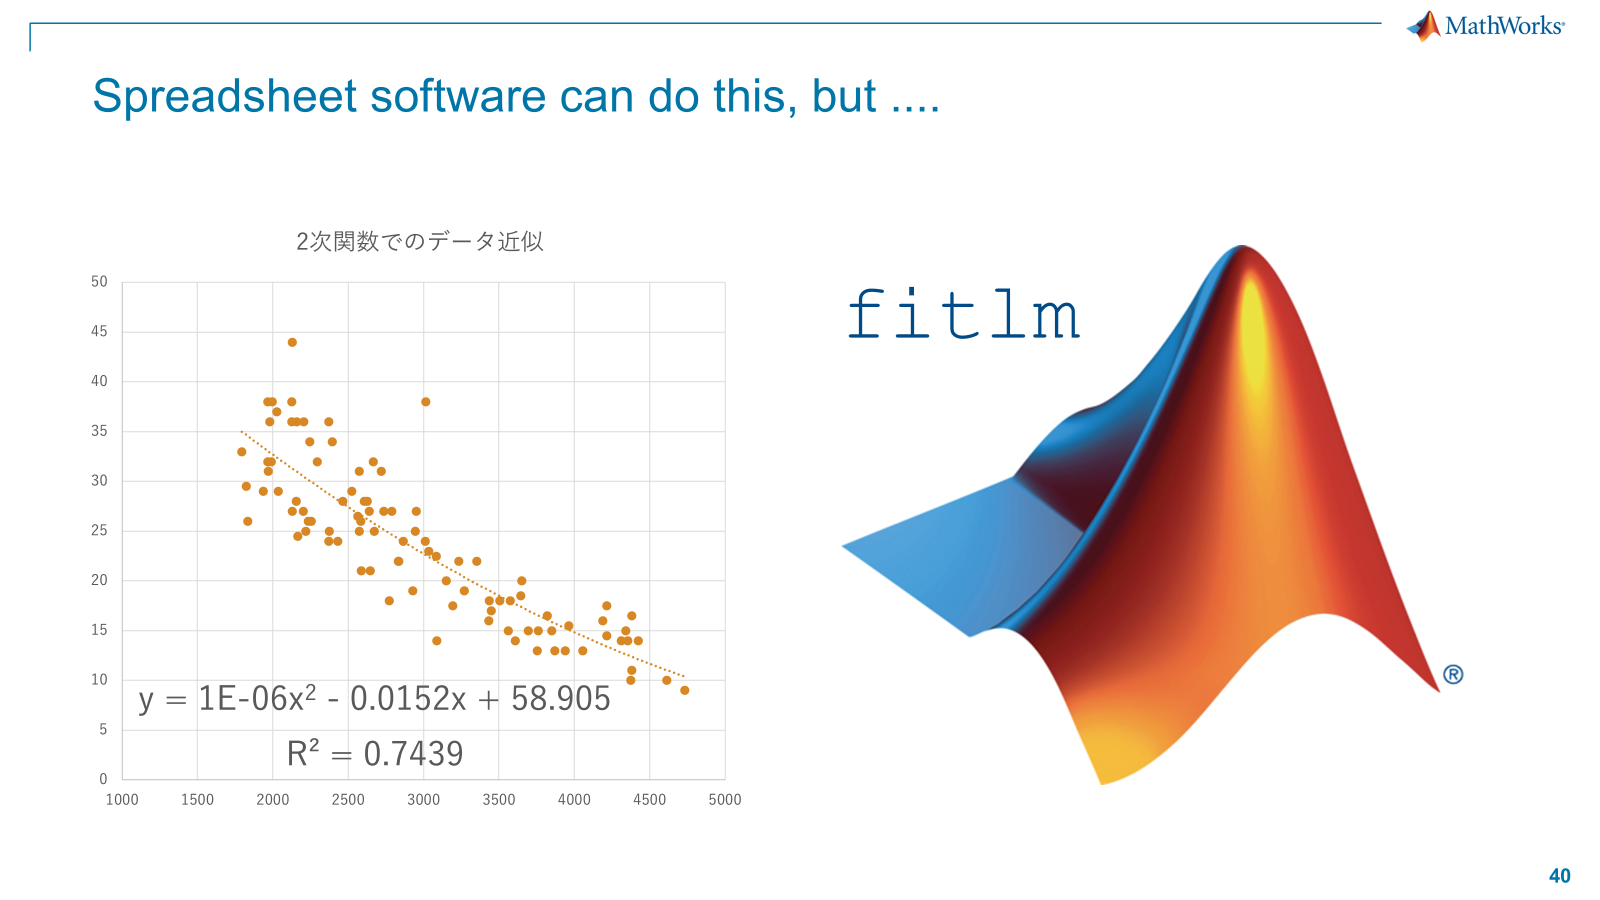

B: 

"(This sounds bad...) Approximation of a quadratic function is also linear regression!" 

"By the way, do you know the definition of linear regression? The key is that it is linear with respect to the parameters. In other words: 


$$\mathbf{y} = X\mathbf{\beta} + \mathbf{\epsilon}$$


If you can express it, it's actually linear regression! 

In an extreme example, 


$$y = \beta_0 + \beta_1\log(x) + \beta_2 x^2 + \beta_3 \sin x$$


is also linear regression.'' 

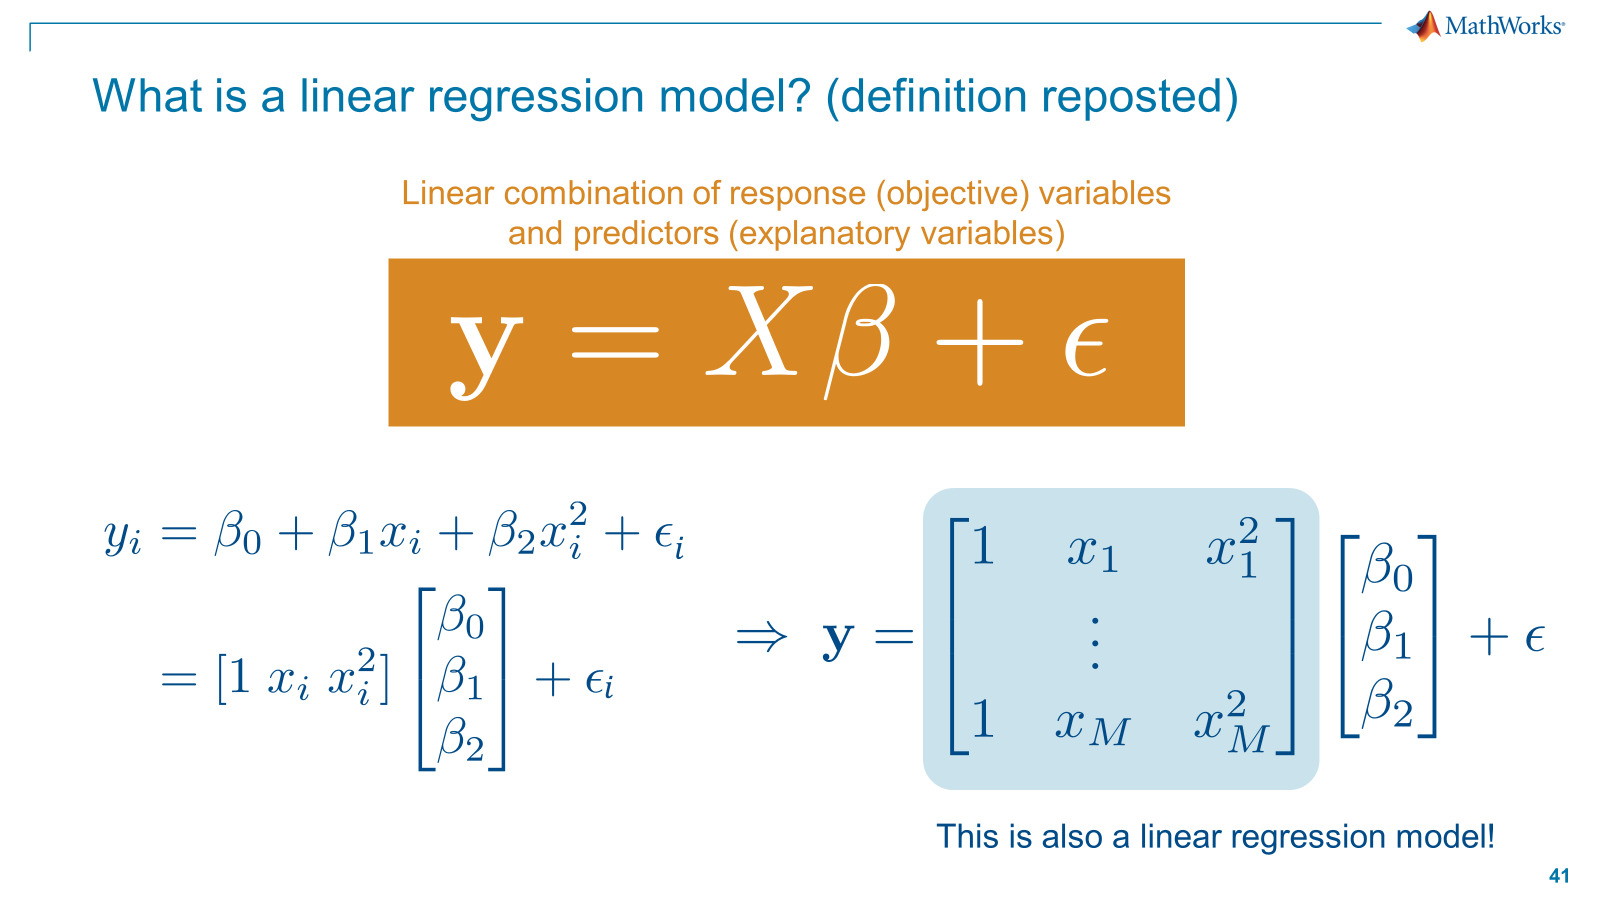

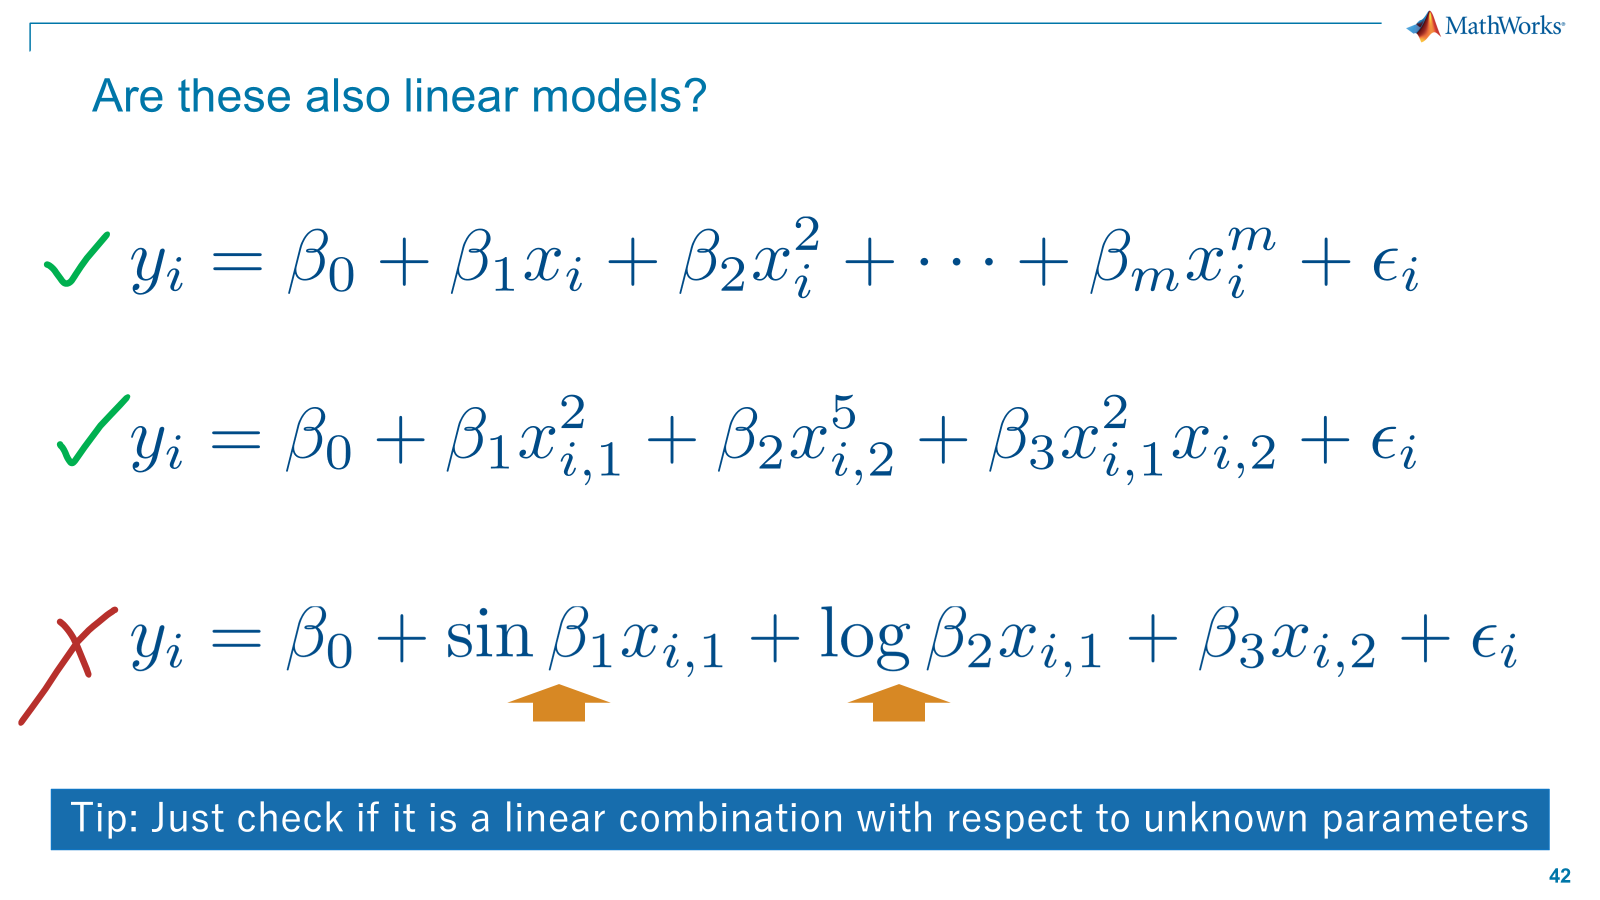

A: 

``I see. The model earlier was a linear function, right? I think I'll increase the order to get a better fit.'' 

``First, let's start with the linear function'' 

linear_mdl_1 = fitlm(tbl,"MPG~1+Weight");
disp(linear_mdl_1);

Linear regression model:
    MPG ~ 1 + Weight

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        49.238        1.6504     29.834    9.0258e-49
    Weight         -0.0086118    0.00053775    -16.014    3.2405e-28


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 4.16
R-squared: 0.738,  Adjusted R-Squared: 0.735
F-statistic vs. constant model: 256, p-value = 3.24e-28


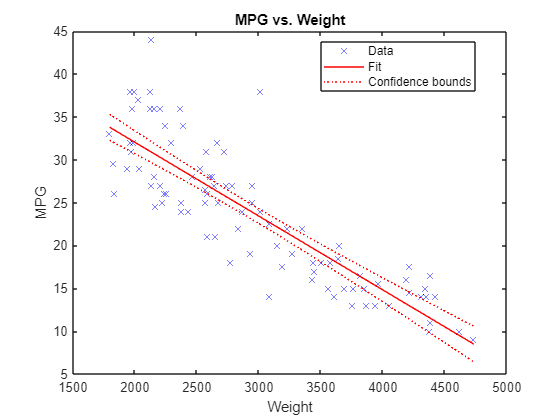

plot(linear_mdl_1); 

A : 

``Let's increase it to the cubic term.... Whoa! This looks good! ” 

linear_mdl_2 = fitlm(tbl,"MPG~1+Weight^3");%fitlm(tbl,"MPG~1+Weight+Weight^2+Weight^3");
disp(linear_mdl_2);

Linear regression model:
    MPG ~ 1 + Weight + Weight^2 + Weight^3

Estimated Coefficients:
                    Estimate         SE         tStat     pValue 
                   __________    __________    _______    _______

    (Intercept)        24.278        28.374    0.85563     0.3945
    Weight            0.02036      0.028588     0.7122     0.4782
    Weight^2       -1.061e-05    9.2644e-06    -1.1452    0.25519
    Weight^3       1.2224e-09    9.6777e-10     1.2631    0.20984


Number of observations: 93, Error degrees of freedom: 89
Root Mean Squared Error: 4.12
R-squared: 0.748,  Adjusted R-Squared: 0.74
F-statistic vs. constant model: 88.3, p-value = 1.4e-26


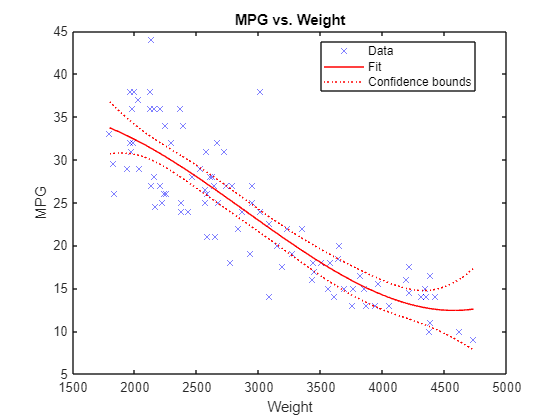

plot(linear_mdl_2); 

B: 

“Wilkinson's notation has become complicated, so I'll summarize it again.” 

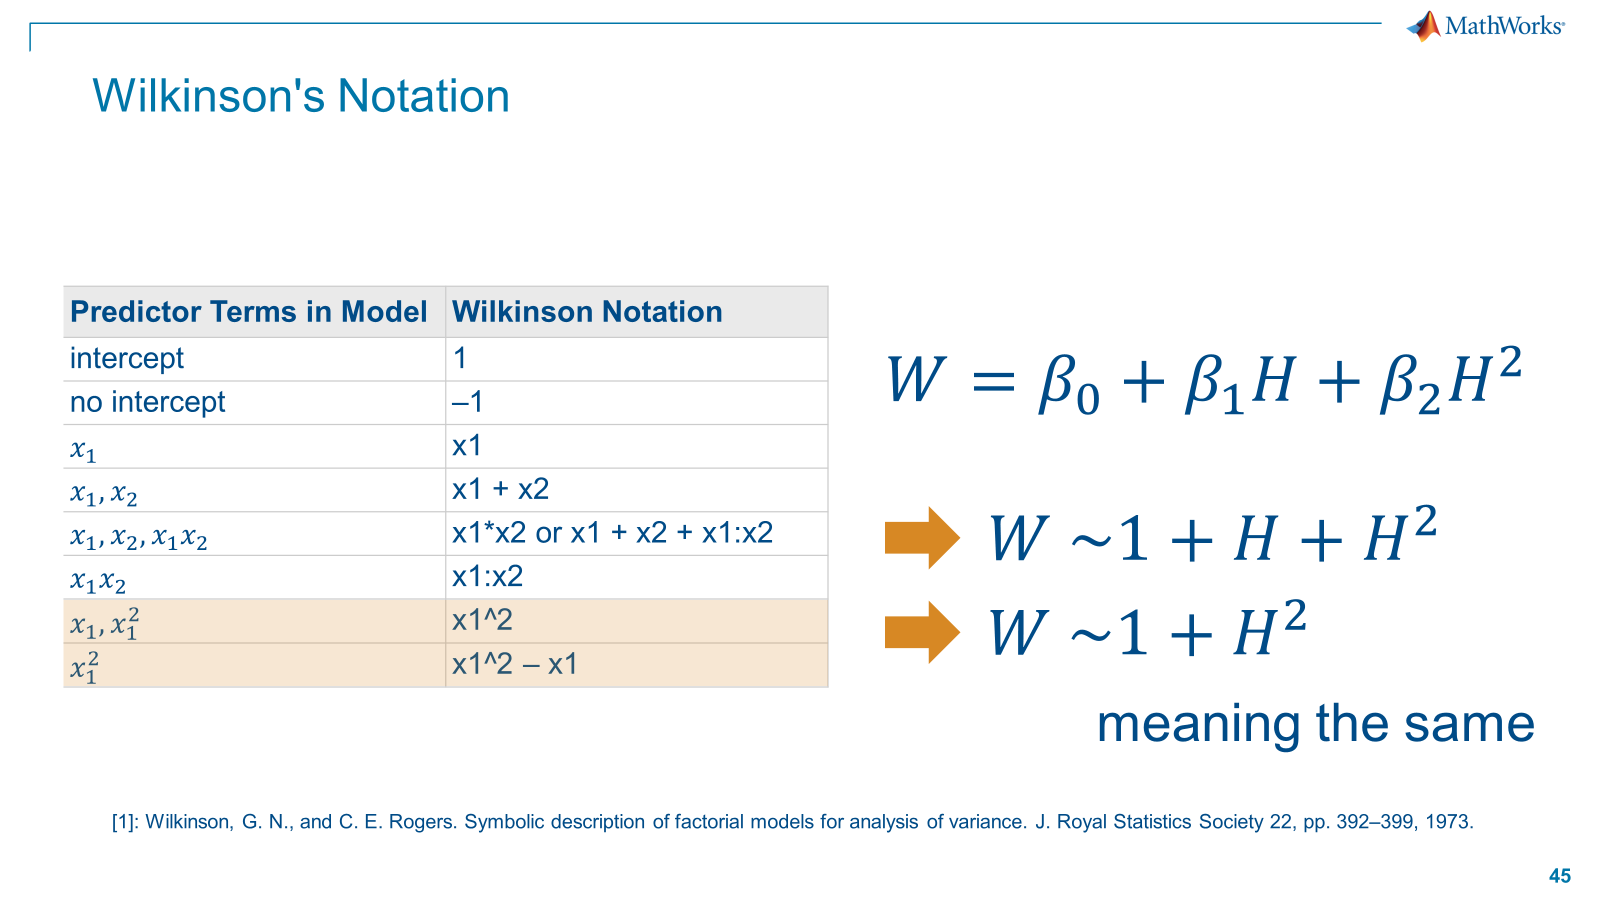

B: 

“Mr. A, which model is better? Also, please tell me why you think so. ” 

A: 

"The coefficient of determination...it seems better to be cubic. Is it better to increase the terms more and more? Hmm..." 

Coefficient of determination 

linear_mdl_1.Rsquared

ans = struct with fields:
    Ordinary: 0.7381
    Adjusted: 0.7352


linear_mdl_2.Rsquared 

ans = struct with fields:
    Ordinary: 0.7485
    Adjusted: 0.7400


A: 

“The model that uses up to the cubic term has a better fitting (coefficient of determination), so this is the better model! (Smug)” 

“Anyway, I wonder what Ordinary and Adjusted are... ” 

####  Question 2.1: What am I overlooking? 

B: 

"Do you remember the definition of coefficient of determination?" 

A: 

"Of course, it is the amount that the model can explain. (Doya 2)" 


$$R^2 = \frac{\sum(\hat{y}_i-\bar{y})^2}{\sum(y_i - \bar{y})^2} = 1 - \frac{\sum(y_i-\hat{y}_i)^2}{\sum(y_i-\bar{y})^2}$$


B: 

"This Doesn't it get bigger and bigger as the model becomes more complex?Does the more complex the model, the better?'' 

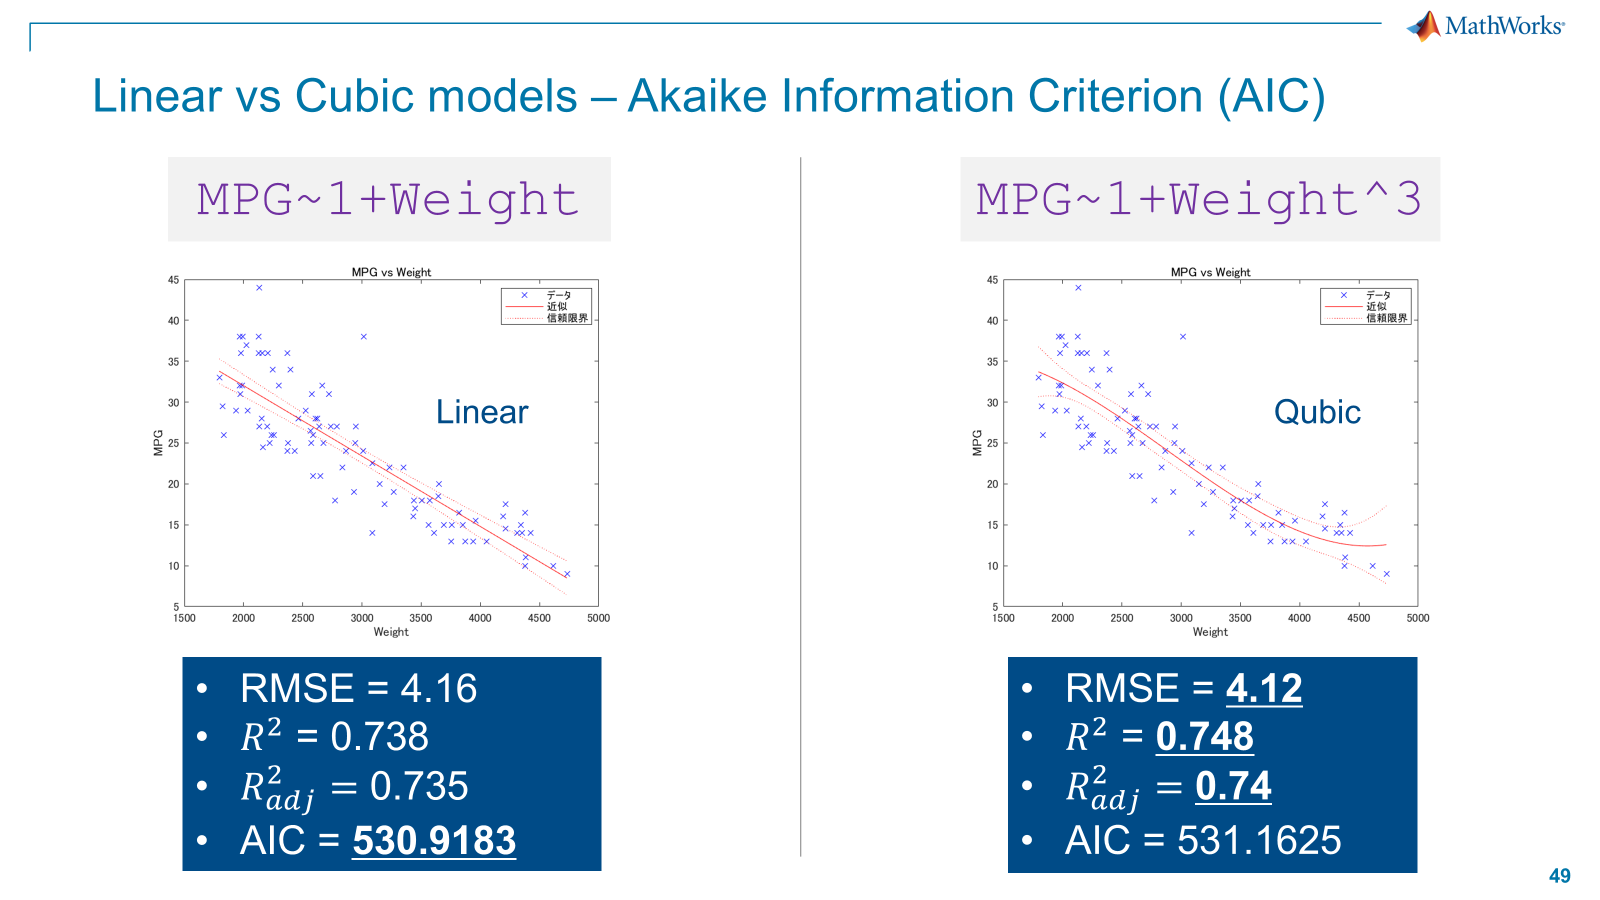

** Answer: ** You're overlooking the penalty for increasing the complexity of the model 

B: 

``By the way, next to the coefficient of determination, there is also a coefficient of determination with adjusted degrees of freedom.Do you know what this is?'' 

A: 

``Ah... now that I think about it.....I'm sure this is an index that also takes into account the model's degrees of freedom (number of parameters), so it can prevent the model from becoming unnecessarily complex." 

"I see... Adjusted R^2 is This is equivalent to this.'' 

``If we use this as an indicator, we can fairly evaluate complex cubic models!'' 

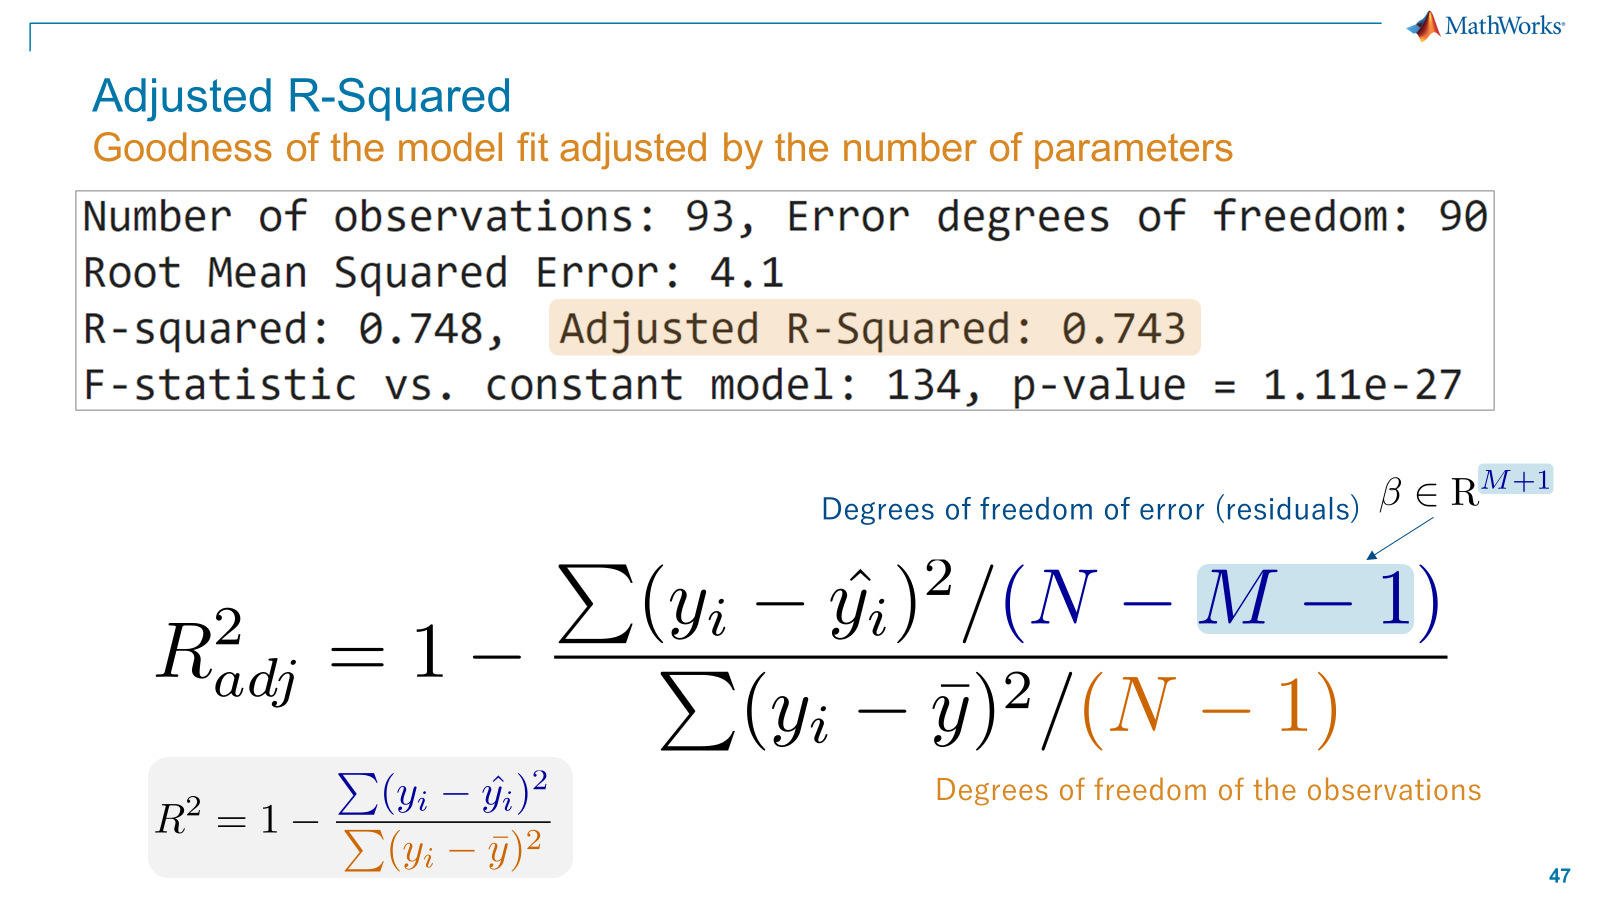

B : 

``That's also a good indicator of fitting. ” 

[Experiment] Fitting results with garbage added 

tblextra = addvars(tbl,rand(height(tbl),1),'NewVariableNames','extra'); % Add random numbers to dataset
linear_mdl_extra = fitlm(tblextra,"MPG~1+Weight+extra"); % Add to the model with the name extra
disp(linear_mdl_extra);

Linear regression model:
    MPG ~ 1 + Weight + extra

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        50.191        1.7793     28.208    1.8165e-46
    Weight         -0.0085679    0.00053595    -15.986    4.9489e-28
    extra             -2.0317        1.4615    -1.3902        0.1679


Number of observations: 93, Error degrees of freedom: 90
Root Mean Squared Error: 4.14
R-squared: 0.744,  Adjusted R-Squared: 0.738
F-statistic vs. constant model: 131, p-value = 2.52e-27


####  Question 2.2: What are other fitting indicators? 

** Answer 1: ** The concept of information criterion that takes overfitting into account Let us know. 

One of the information criterion model selection methods is the minimum AIC method: 

linear_mdl_1.ModelCriterion.AIC

ans = 530.9183

linear_mdl_2.ModelCriterion.AIC 

ans = 531.1625

Information criterion - The similarity between the model from which the data was generated and the estimated model is used as an index. A standard that focuses on whether future predictions will be successful, rather than "how the data fits." Although it is originally a concept of data fitting using maximum likelihood estimation, the least squares method assumes a normal distribution as the probability density distribution, and the maximum likelihood estimation solution = least squares solution, so this index can be used.. 


$$AIC = -2\log L(\mathbf{\theta}) + 2k$$


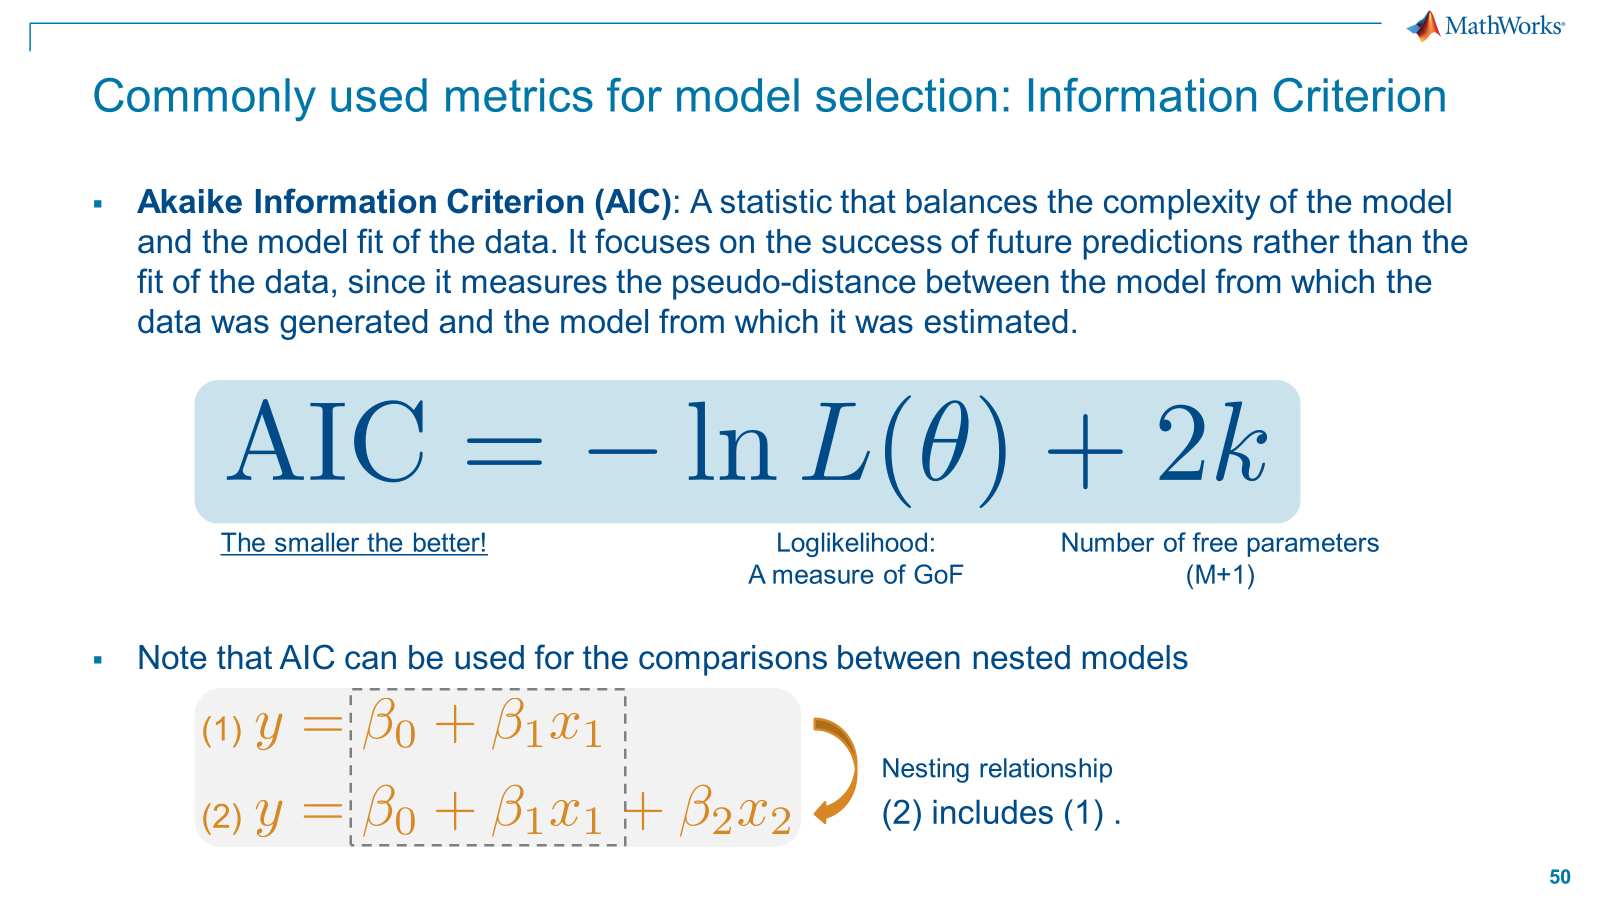

** Answer 2 ** : Automatically selects the best model while checking whether the added terms are meaningful 

yourMethod = 'aic' % Choose from 3

yourMethod = 'aic'

stepwise_mdl = stepwiselm(tbl,'MPG ~ Weight', 'Upper', 'poly300000','Criterion',yourMethod,'verbose',2) 

   Change in AIC for adding Weight^2 is -0.10342
1. Adding Weight^2, AIC = 530.8149
   Change in AIC for adding Weight^3 is 0.34758
   No candidate terms to remove


stepwise_mdl = Linear regression model:
    MPG ~ 1 + Weight + Weight^2

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        59.015        7.0087     8.4203    5.5134e-13
    Weight          -0.015268     0.0046698    -3.2695     0.0015269
    Weight^2       1.0556e-06    7.3569e-07     1.4348        0.1548


Number of observations: 93, Error degrees of freedom: 90
Root Mean Squared Error: 4.13
R-squared: 0.744,  Adjusted R-Squared: 0.738
F-statistic vs. constant model: 131, p-value = 2.37e-27

** Supplement to answer 2 ** : The F value is a constant model with $F = \frac{\text{Residual of constant model}}{\text{Residual of fitted model}}$ as the test statistic. This will help you determine whether there is a difference (meaningful) between the model you are considering and the model you are considering. In this case, the null hypothesis is that $H_0:
$ all the coefficients are 0, and the $H_1:$ alternative hypothesis is that at least one of the coefficients is not 0. 

`stepwiselm` is a method of searching for a better model step by step by adding or subtracting terms while looking at indicators. 

stepwise - GUI Tool 

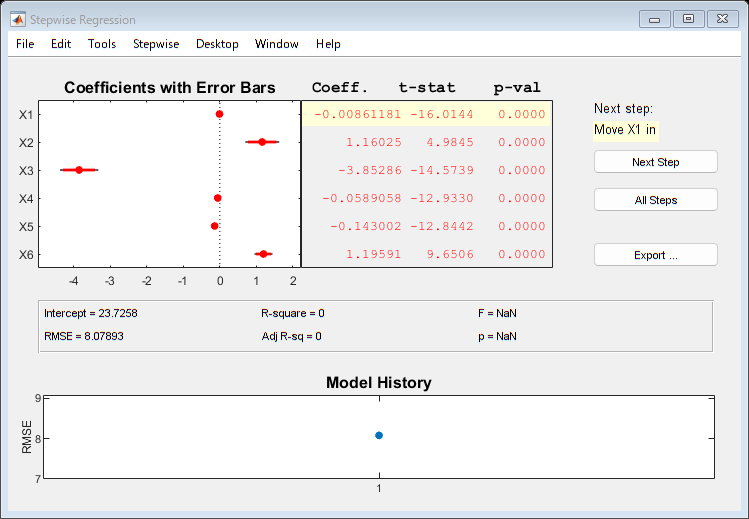

stepwise(tbl{:,["Weight","Acceleration","Cylinders","Displacement","Horsepower","Model_Year"]},tbl.MPG)

###  (for self-study) Tool introduction 

methods(linear_mdl_1) % properties(linear_mdl_1) 

Methods for class LinearModel:

addTerms               anova                  coefCI                 coefTest               compact                disp                   dwtest                 feval                  gather                 partialDependence      plot                   plotAdded              plotAdjustedResponse   plotDiagnostics        plotEffects            plotInteraction        plotPartialDependence  plotResiduals          plotSlice              predict                random                 removeTerms            step                   



** Residual plot you should look at first ** - Is it a normal distribution shape? Check 

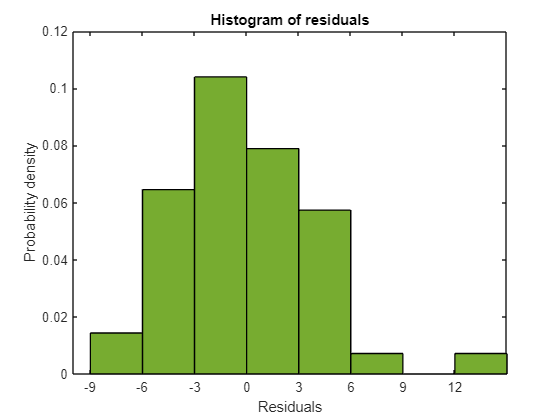

plotResiduals(linear_mdl_1) 

** Leverage plot ** - Check for observations that have too much influence on model estimation 


$$\hat{y}_k = h_{1k}y_1 + h_{2k}y_2 + \cdots+h_{kk}y_k + \cdots + h_{nk}y_n \\
h_{kk} \quad \text{: lever ratio}$$


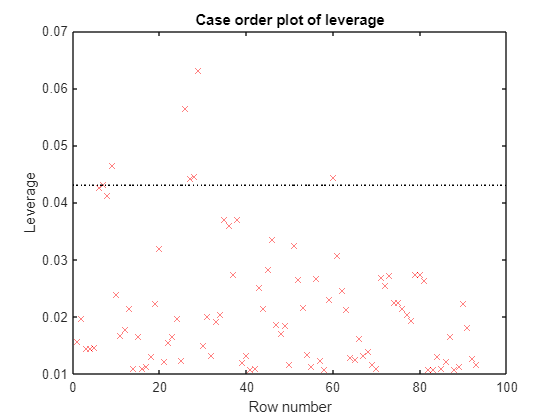

plotDiagnostics(linear_mdl_1) 

** "Leverage" data ** - Recommended threshold * 2p/n * (p is the parameter number) 

% Approximate leverage ratio
t_leverage_threshold = 2*linear_mdl_1.NumCoefficients/linear_mdl_1.NumObservations

t_leverage_threshold = 0.0430

% Leverage data
t_leverage_actual = linear_mdl_1.Diagnostics.Leverage;
% Search for data above the threshold
find(t_leverage_actual > t_leverage_threshold) 

ans =      7
     9
    26
    27
    28
    29
    60


* From this point on, a "warning" will appear in the calculation, but there is a reason. The reason will be retrieved later. 

** Check the significance of the model/model components ** - ANOVA (Are the coefficients significant for the response $y$, F-test vs constant model) 

anova(stepwise_mdl) 

ans = 3×5 table
                SumSq     DF    MeanSq      F         pValue  
                ______    __    ______    ______    __________

    Weight      4432.1     1    4432.1    259.45    2.9886e-28
    Weight^2     35.17     1     35.17    2.0588        0.1548
    Error       1537.5    90    17.083                        


** Linear hypothesis test on the coefficients of a linear regression model **

Constant model Testing the significance of the model 

[p, F] = coefTest(stepwise_mdl) 

p = 2.3659e-27

F = 130.7524

** Checking the autocorrelation of the residuals - ** Durbin-Watson test 

Checking whether the residuals (model noise) satisfy the assumption that they are independently distributed. 


$$d \sim (0, 4)$$


If the positive autocorrelation is strong, $d\rightarrow0$

d = dwtest(stepwise_mdl) 

d = 4.1681e-07

** Select the parameters and check the model. **

It is called an additional variable plot or partial regression lever plot. Check the influence of one variable from a regression (multiple regression) model consisting of multiple variables. 

`plotAdded` (model, [parameter number used]) 

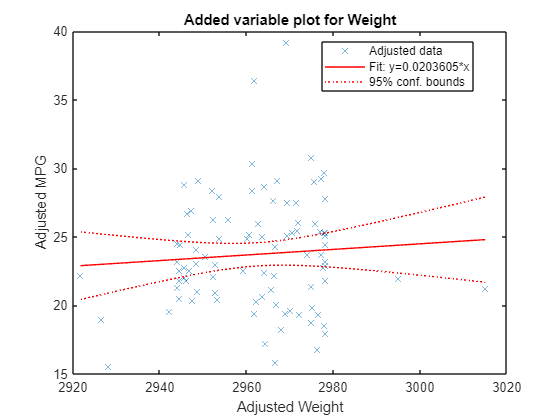

plotAdded(linear_mdl_2,"Weight")

###  3. Fragile linear regression 

A: 

"Next time, I would like to add Model_Year and perform regression. It's called multiple regression analysis." 

tbl.Model_Year = categorical(tbl.Model_Year);
mcol_fine = fitlm(tbl,"MPG~1 + Weight + Model_Year");
disp(mcol_fine);

Linear regression model:
    MPG ~ 1 + Weight + Model_Year

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          39.897        1.5305     26.068    1.9419e-43
    Weight           -0.0065843    0.00042509    -15.489    5.3727e-27
    Model_Year_76        1.9477       0.73977     2.6329     0.0099823
    Model_Year_82        8.1301       0.85057     9.5585    2.6198e-15


Number of observations: 93, Error degrees of freedom: 89
Root Mean Squared Error: 2.88
R-squared: 0.877,  Adjusted R-Squared: 0.873
F-statistic vs. constant model: 211, p-value = 2.53e-40


B: 

"Compared to the first model (bottom), the coefficient of determination is significantly improved." 

"I'll update Wilkinson's notation again." 

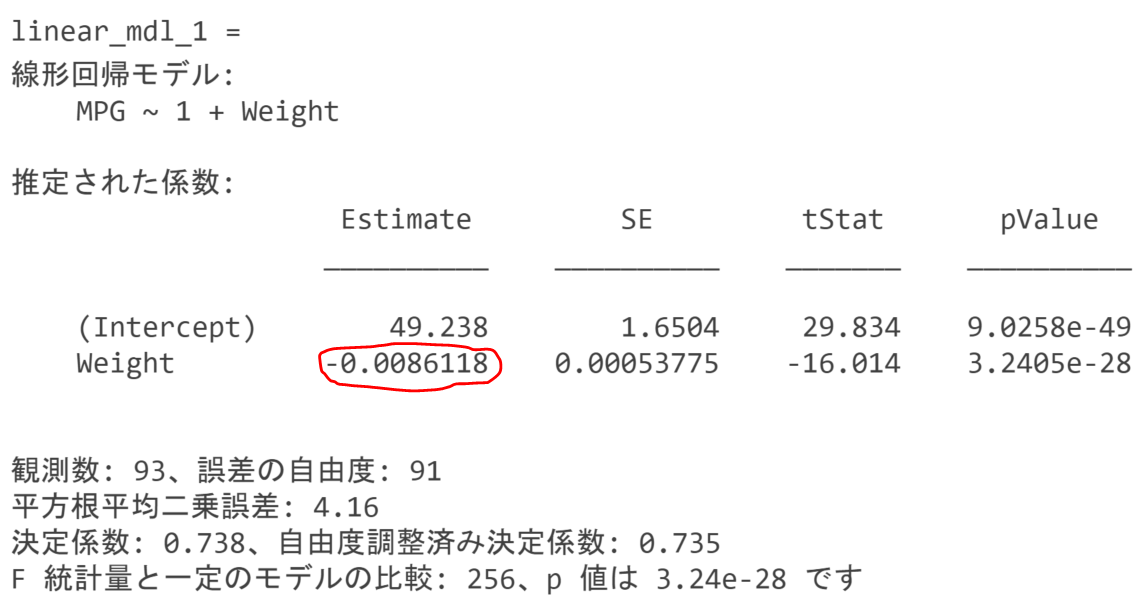

B: 

" Now, Mr. A, let's add Horsepower and do a multiple regression analysis (grin)" 

mcol_horp = fitlm(tbl,"MPG~1 + Weight + Model_Year + Horsepower");
disp(mcol_horp); 

Linear regression model:
    MPG ~ 1 + Weight + Horsepower + Model_Year

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          39.863        1.5289     26.072    3.6414e-43
    Weight           -0.0057673    0.00085191    -6.7698     1.384e-09
    Horsepower        -0.018408      0.016641    -1.1062       0.27166
    Model_Year_76        1.3281       0.92714     1.4325       0.15554
    Model_Year_82        7.6755       0.94371     8.1333    2.4757e-12


Number of observations: 93, Error degrees of freedom: 88
Root Mean Squared Error: 2.88
R-squared: 0.878,  Adjusted R-Squared: 0.873
F-statistic vs. constant model: 159, p-value = 2.1

A: 

"It doesn't seem like the performance has improved much, but it looks a little different...hmm." 

B: 

"You've noticed. We've reached the stage where we need to consider other indicators that we've been neglecting until now..." 

"Let's also check the information-based metrics." 

mcol_horp.ModelCriterion

ans = struct with fields:
     AIC: 465.5910
    AICc: 466.2807
     BIC: 478.2540
    CAIC: 483.2540


mcol_fine.ModelCriterion

ans = struct with fields:
     AIC: 464.8753
    AICc: 465.3299
     BIC: 475.0057
    CAIC: 479.0057


####  Discussion 2: Which model is better? 

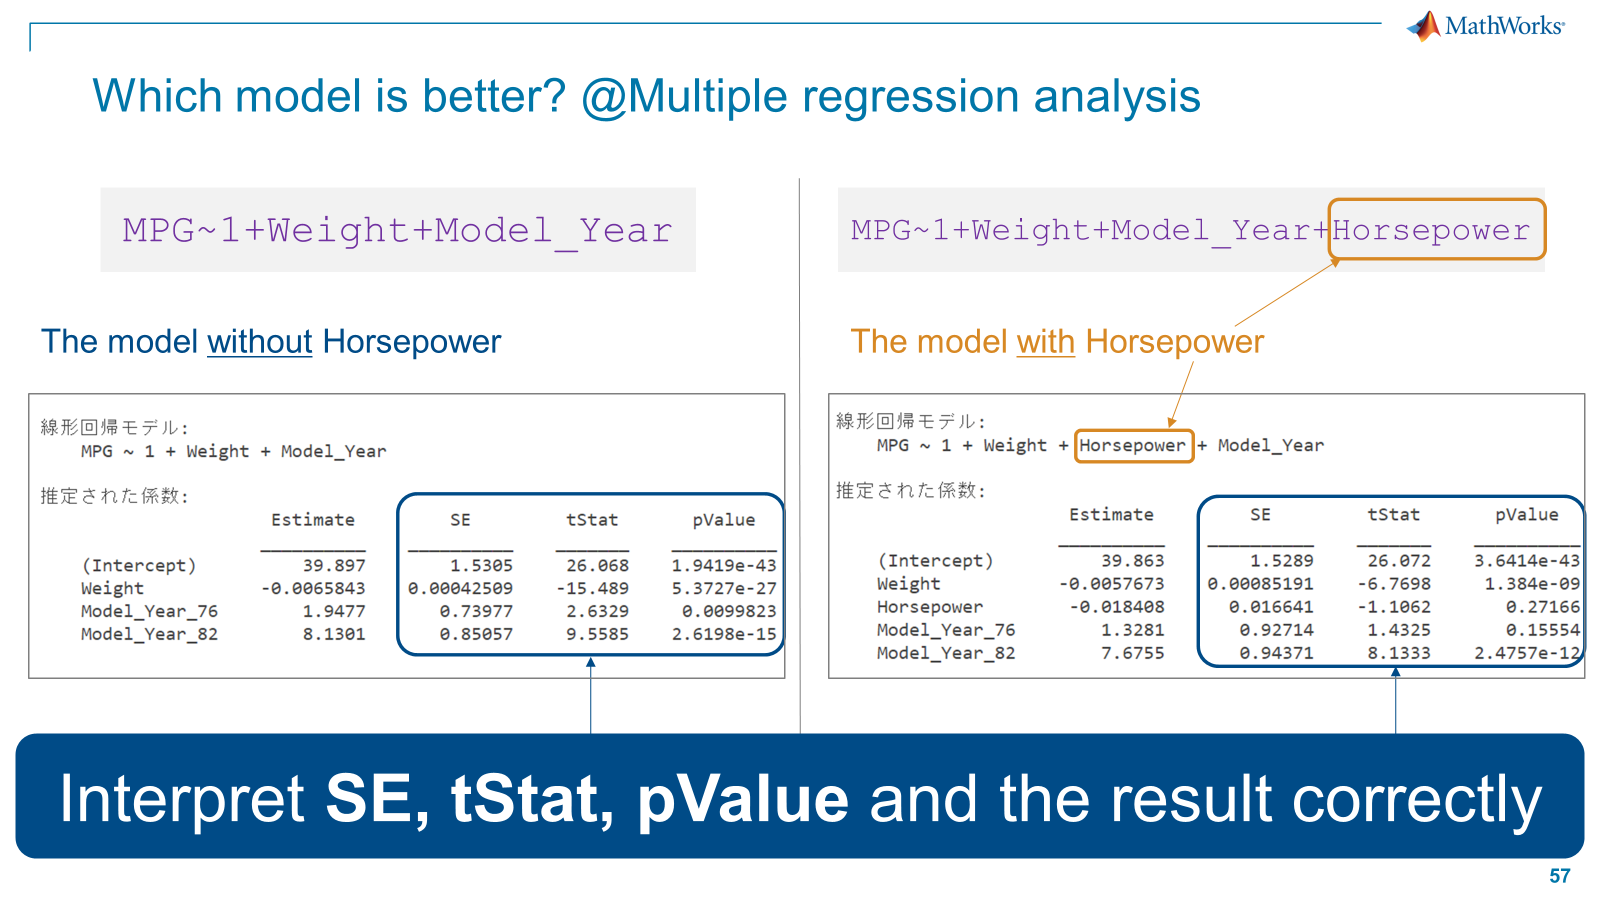

####  Question 3.1: Interpret the results correctly 

** Answer: **

* SE *

The parameters obtained in linear regression follow a normal distribution. 

This is because linear regression assumes a normal distribution for the probability density distribution of noise. 


$$\hat{\mathbf{\beta}} \sim N(\mathbf{\beta}, \sigma^2 (X^TX)^{-1})$$


The root of this variance is SE (Standard Error) - therefore, it can be taken as an indicator of "parameter certainty." 

It is proportional to the size of measurement/observation noise and increases even when there is multicollinearity. 

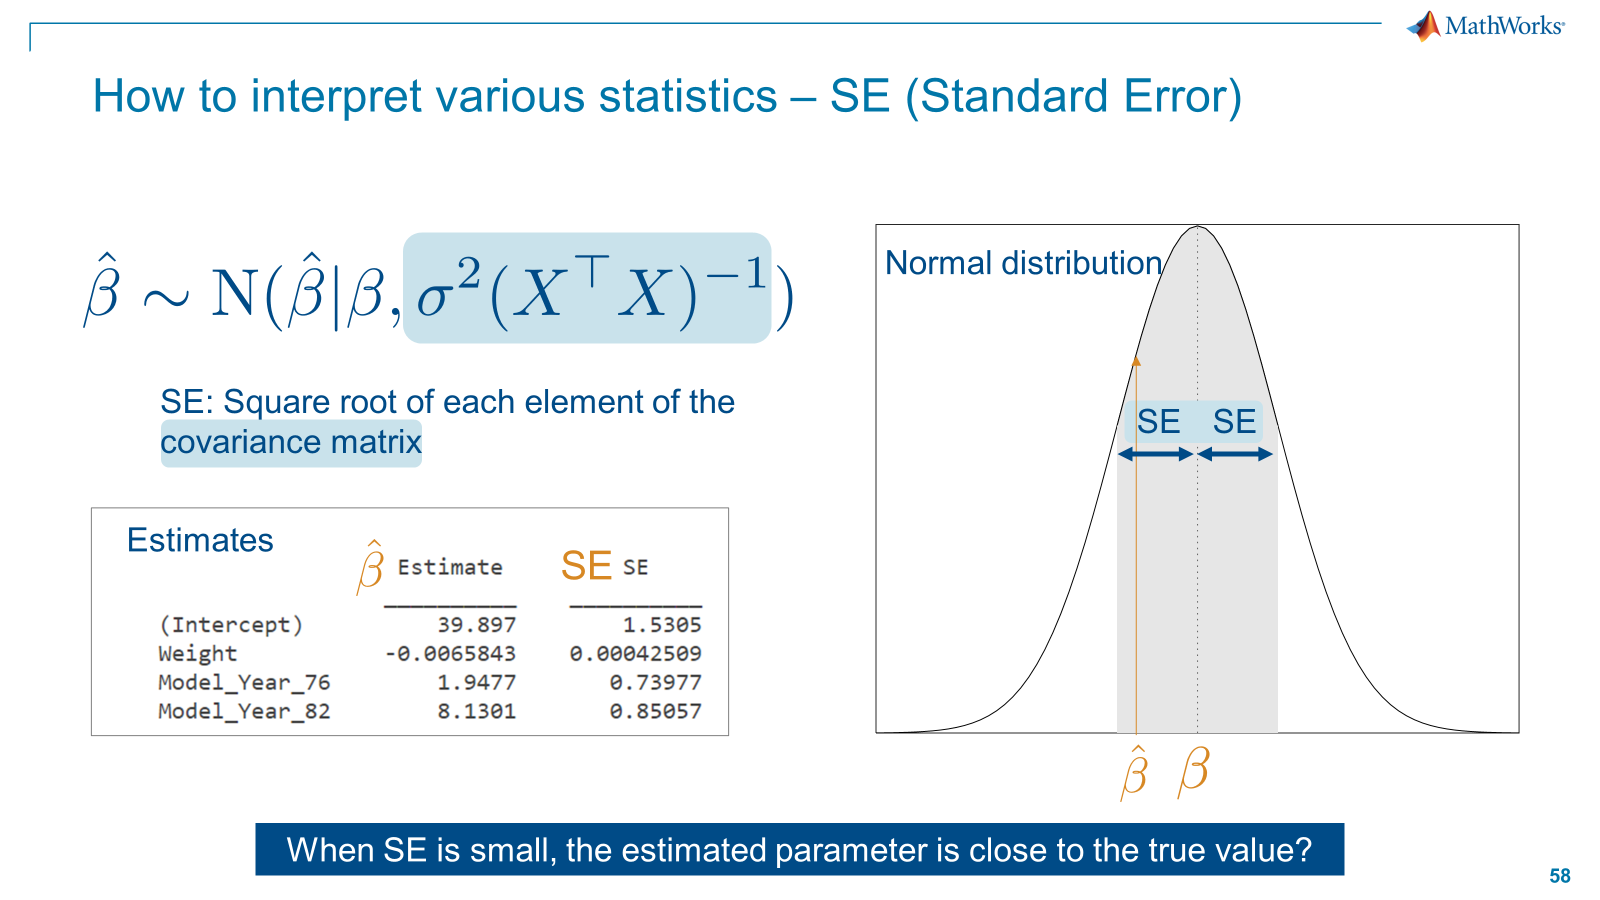

* tStat *

t-value during t-test of null hypothesis $\beta_i = 0$. The larger this value, the less likely the parameter is zero. Since 

is a value from the t distribution, no judgment can be made from the value itself unless the degrees of freedom are considered. 

`tStat = Estimate/SE`

* pValue *

Probability value for comparing t-value with significance level. Probability of greater than or equal to t value in t distribution. 

Look at this value and compare it with the significance level (set by yourself) to decide whether to reject $\beta_i = 0$. 

A small p-value means that the coefficient of the variable is not zero (that is, it is significant). 

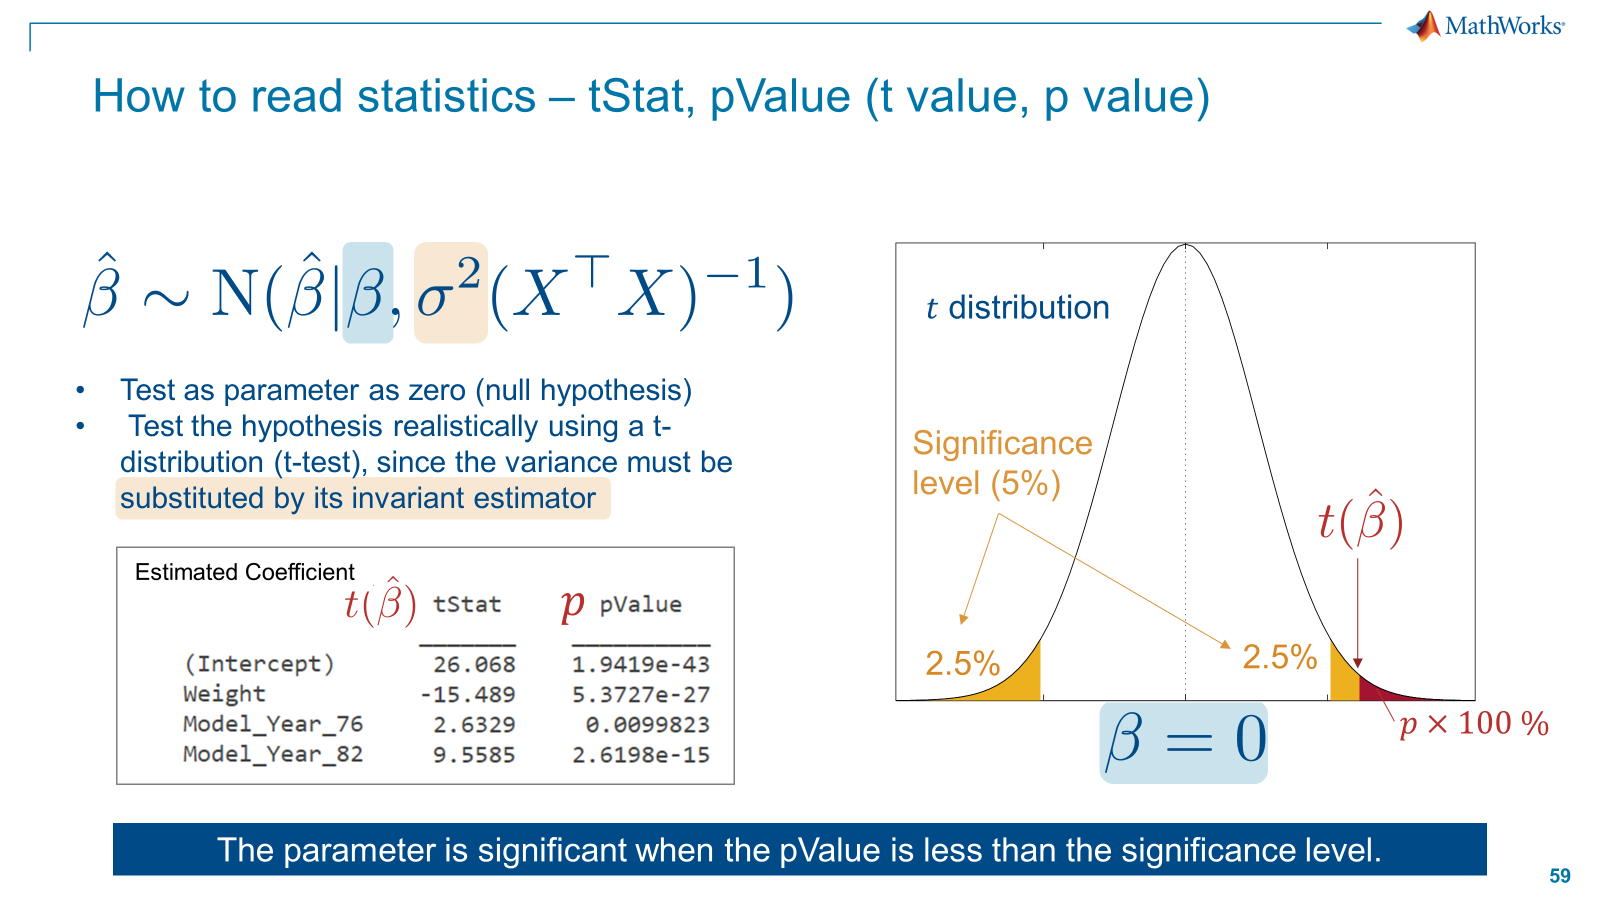

####  Question 3.2: Which model is better in the end and what is the root cause of that conclusion?

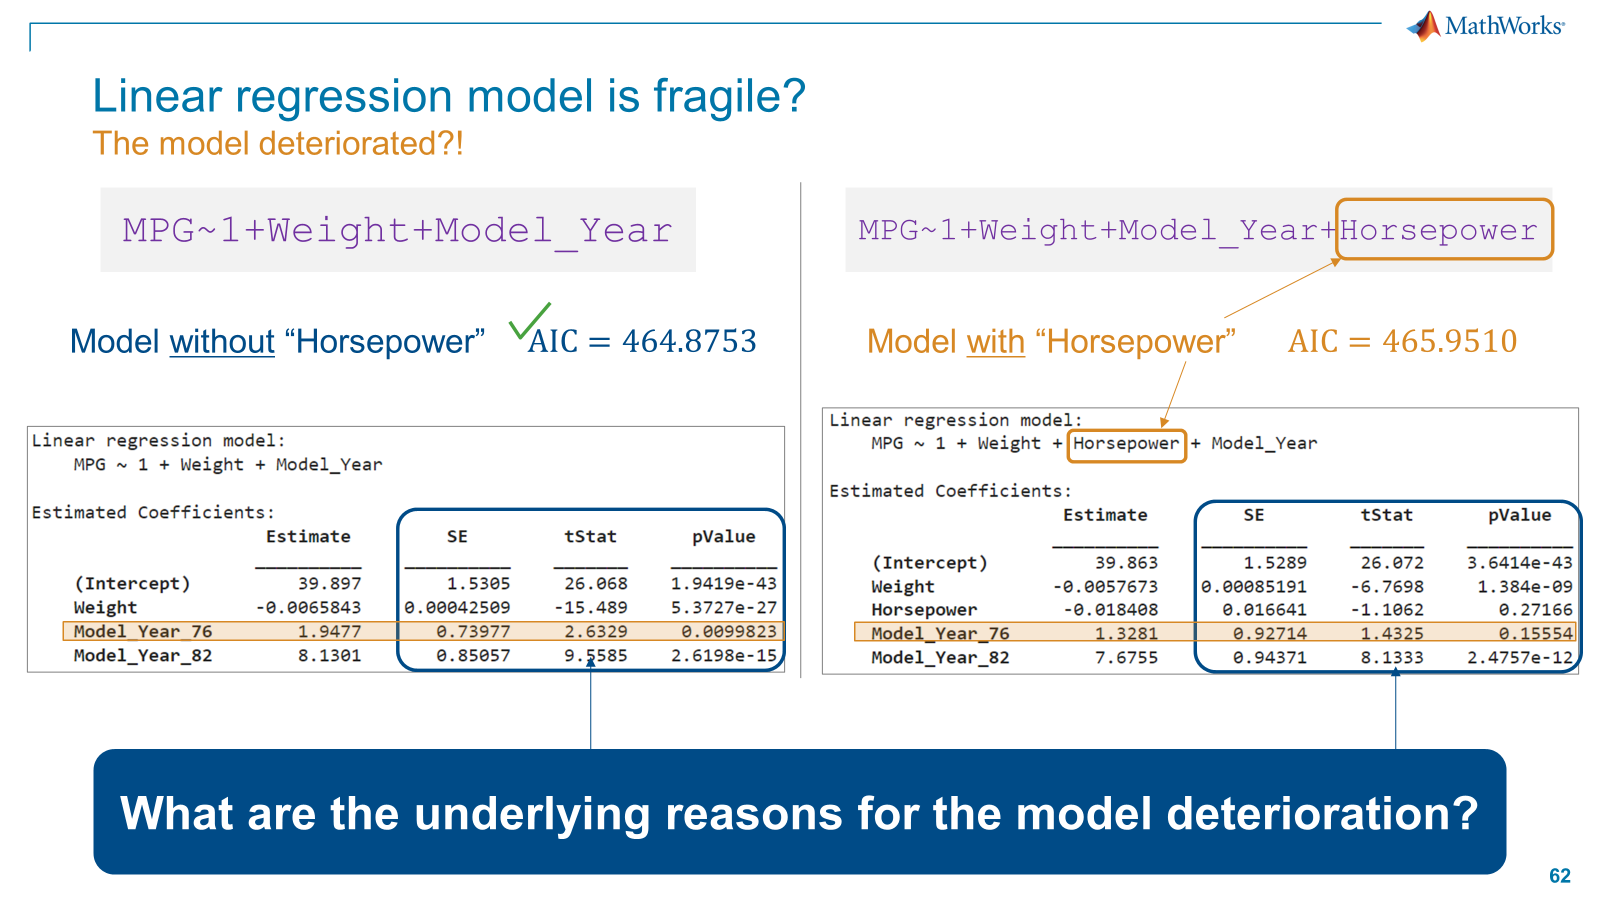

** Answer: It is better not to add Horsepower. Because of multicollinearity. **

Explain multicollinearity based on theory. The least squares solution of 

$\mathbf{y} = X\mathbf{\beta} + \mathbf{\epsilon}$ is $\hat{\mathbf{\beta}} = (X^TX)^{-1}X^T\mathbf{y}$

$X = U\Lambda V^T$ : Singular value decomposition If the column vectors of 


$$(X^TX)^{-1}X^T = \sum\frac{1}{\gamma_j}\mathbf{v}_j\mathbf{u}_j^T\\
\therefore \hat{\mathbf{\beta}} = \mathbf{\beta} + \sum\frac{1}{\gamma_j}\mathbf{v}_j\mathbf{u}_j^T \mathbf{\epsilon}$$


$X$ have high correlation, the value of $\gamma$ tends to be small. 

In that case, the least squares solution becomes unstable. 

In other words, 

Multicollinearity means that if the column vectors of $X$ are highly correlated, the solution becomes questionable. (Not necessarily a column, but refers to a state that is close to a rank drop) 

You should check the correlation coefficient in advance and avoid estimating suspicious regression! 

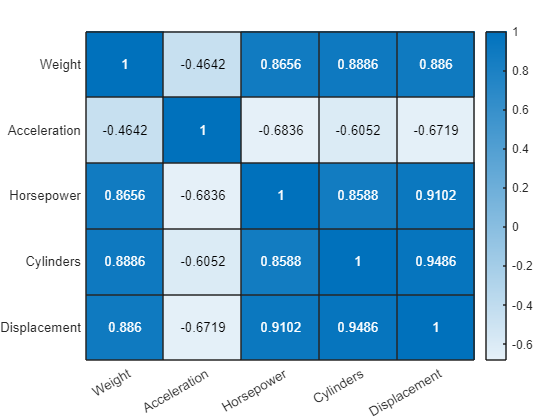

corrNames = ["Weight","Acceleration","Horsepower","Cylinders","Displacement"];
corrTbl = corrcoef(table2array(tbl(:,corrNames)));
heatmap(corrTbl,"XData",corrNames,"YData",corrNames); 

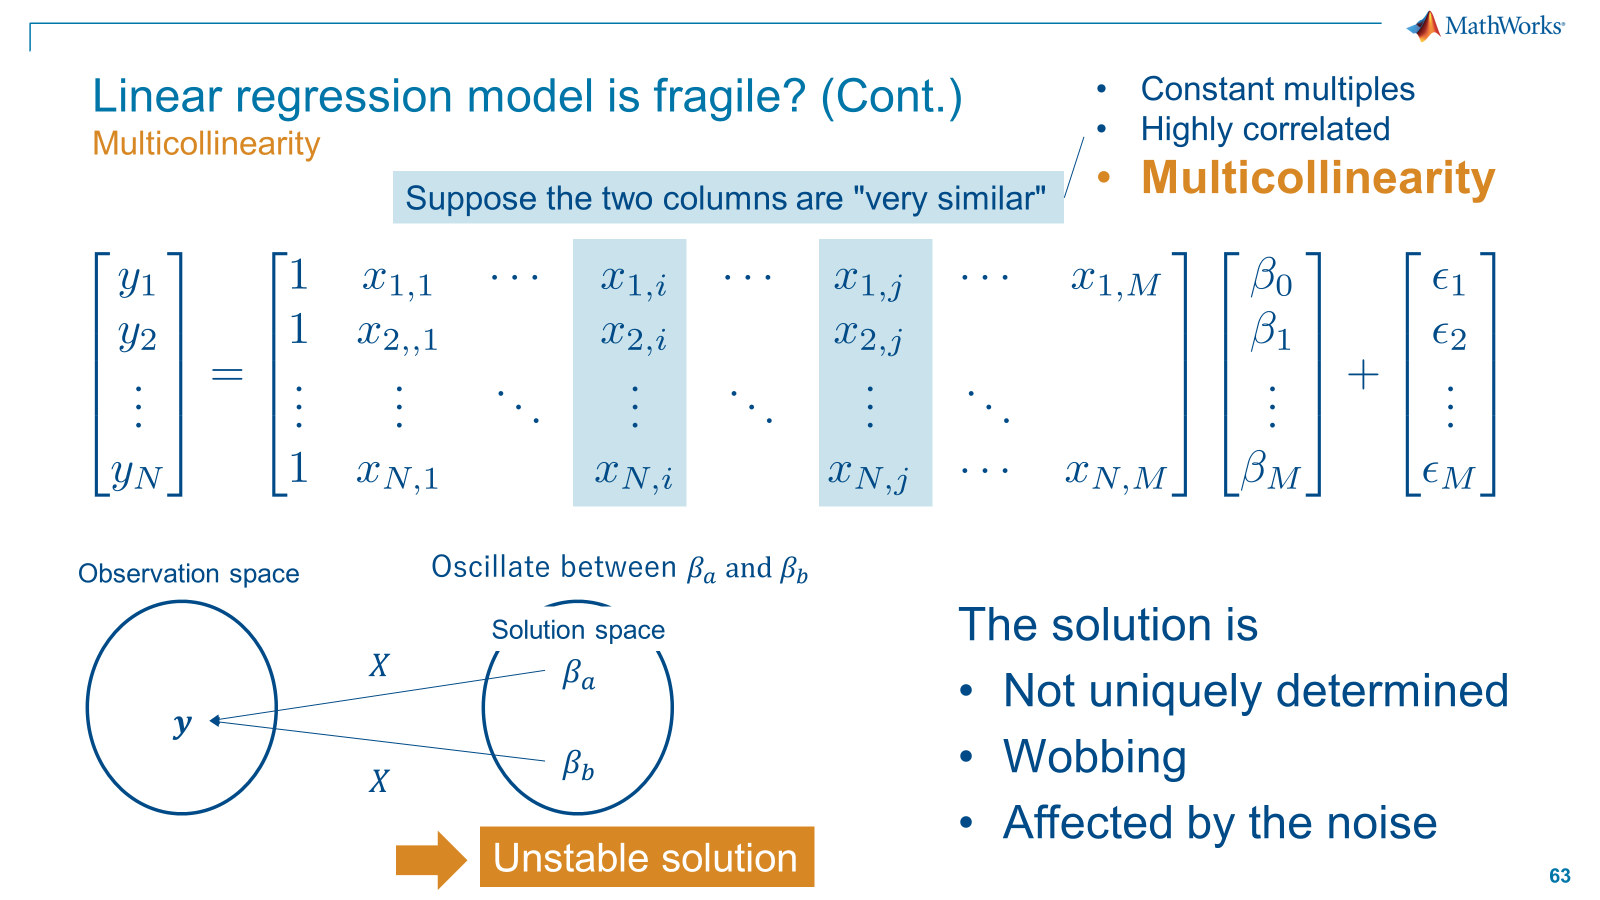

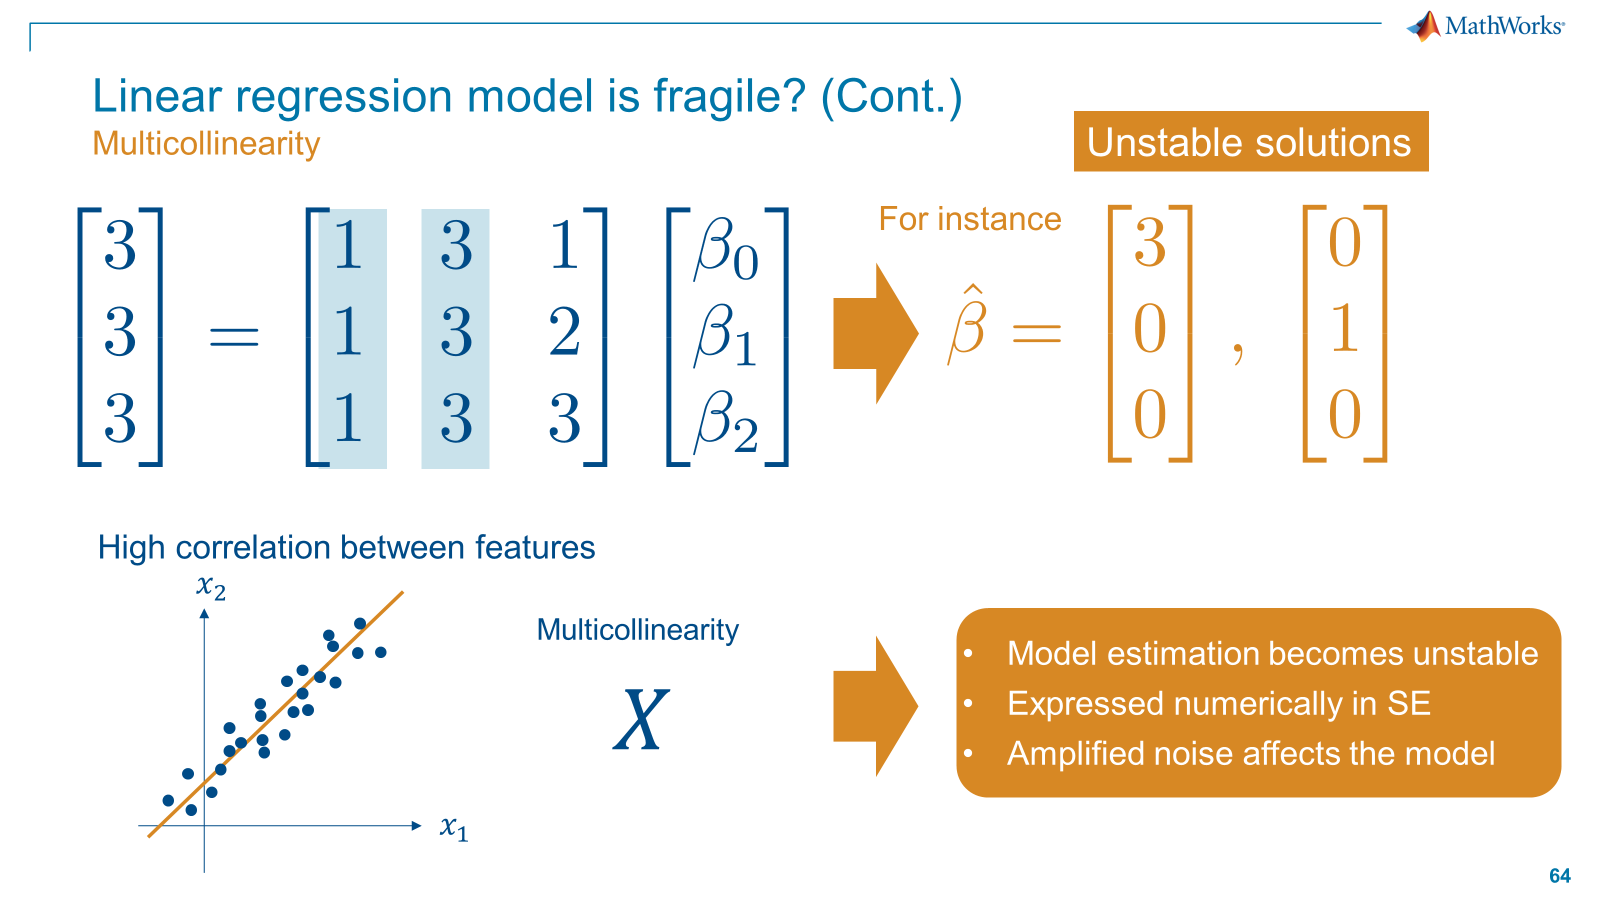

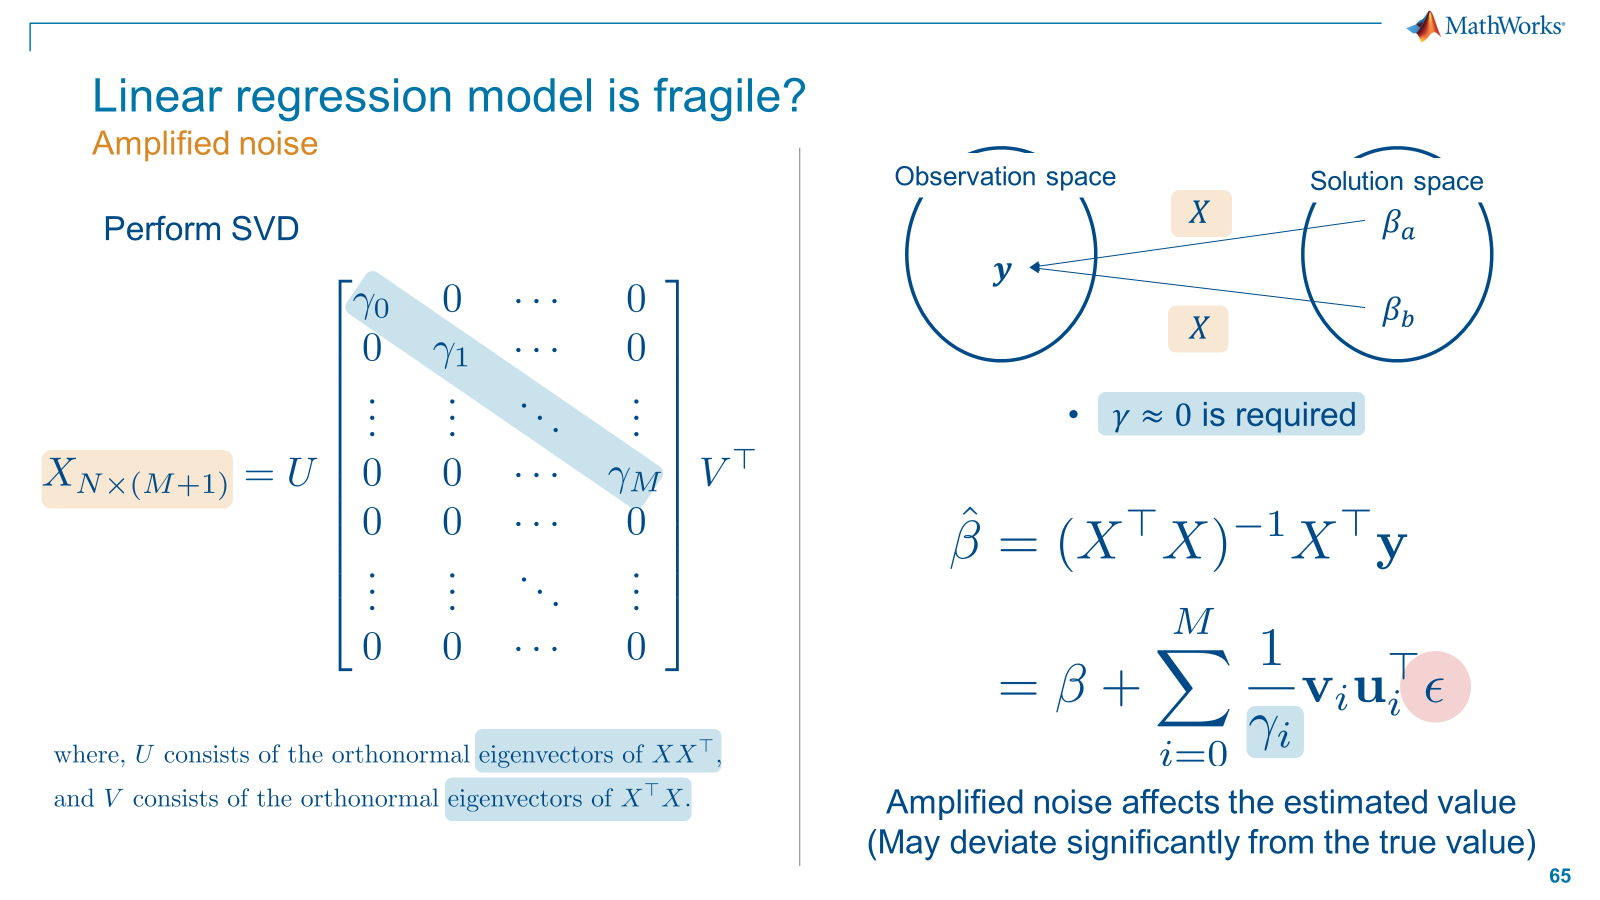

A: 

``Looking at the correlation map, you can see that displacement and You can see that Horsepower has a very high correlation.'' 

``If you intentionally include both, the p-value should be very large...'' 

mcol_Disp = fitlm(tbl,"MPG~1 + Weight + Model_Year + Displacement + Horsepower");
disp(mcol_Disp); 

Linear regression model:
    MPG ~ 1 + Weight + Horsepower + Displacement + Model_Year

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          40.214        1.6905     23.789    7.6648e-40
    Weight           -0.0059711    0.00094879    -6.2933    1.2174e-08
    Horsepower        -0.023284       0.01938    -1.2014       0.23285
    Displacement      0.0037551     0.0075575    0.49687       0.62053
    Model_Year_76        1.3545       0.93264     1.4523       0.15002
    Model_Year_82        7.7362       0.95563     8.0954    3.1667e-12


Number of observations: 93, Error degrees of freedom: 87
Root Mean Squared Erro

B: 

``In this model, Weight and I think that if we include Model_year in addition to Acceleration, we can make stable estimations.'' 

###  4. Data standardization 

A: 

``Now that I understand the indicators, I thought... However, since it is 


$$x \sim \mathbf{Pr}(x|\mathbf{\theta})\\
V(x) = \sigma^2 \; \rightarrow V(10x) = 100\sigma^2$$


for the random variable $x$, wouldn't the standard error change if the units are different, and wouldn't it be impossible to directly compare the effects on the objective variable?" 

B: 

"That's correct..Take a look here. Create a regression model by converting the weight Weight to kg >> ton." 

mcol_org = fitlm(tbl,'MPG~1 + Weight + Cylinders');
disp(mcol_org);

Linear regression model:
    MPG ~ 1 + Weight + Cylinders

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        48.912       1.5801     30.954    9.2075e-50
    Weight         -0.0055097    0.0011201    -4.9187    3.9038e-06
    Cylinders         -1.6037      0.51458    -3.1165     0.0024566


Number of observations: 93, Error degrees of freedom: 90
Root Mean Squared Error: 3.97
R-squared: 0.764,  Adjusted R-Squared: 0.758
F-statistic vs. constant model: 145, p-value = 6.5e-29


% kg >> ton
tbl.Weight = tbl.Weight /1000;
mcol_ton = fitlm(tbl,'MPG~1 + Weight + Cylinders');
disp(mcol_ton);

Linear regression model:
    MPG ~ 1 + Weight + Cylinders

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     48.912      1.5801     30.954    9.2075e-50
    Weight         -5.5097      1.1201    -4.9187    3.9038e-06
    Cylinders      -1.6037     0.51458    -3.1165     0.0024566


Number of observations: 93, Error degrees of freedom: 90
Root Mean Squared Error: 3.97
R-squared: 0.764,  Adjusted R-Squared: 0.758
F-statistic vs. constant model: 145, p-value = 6.5e-29


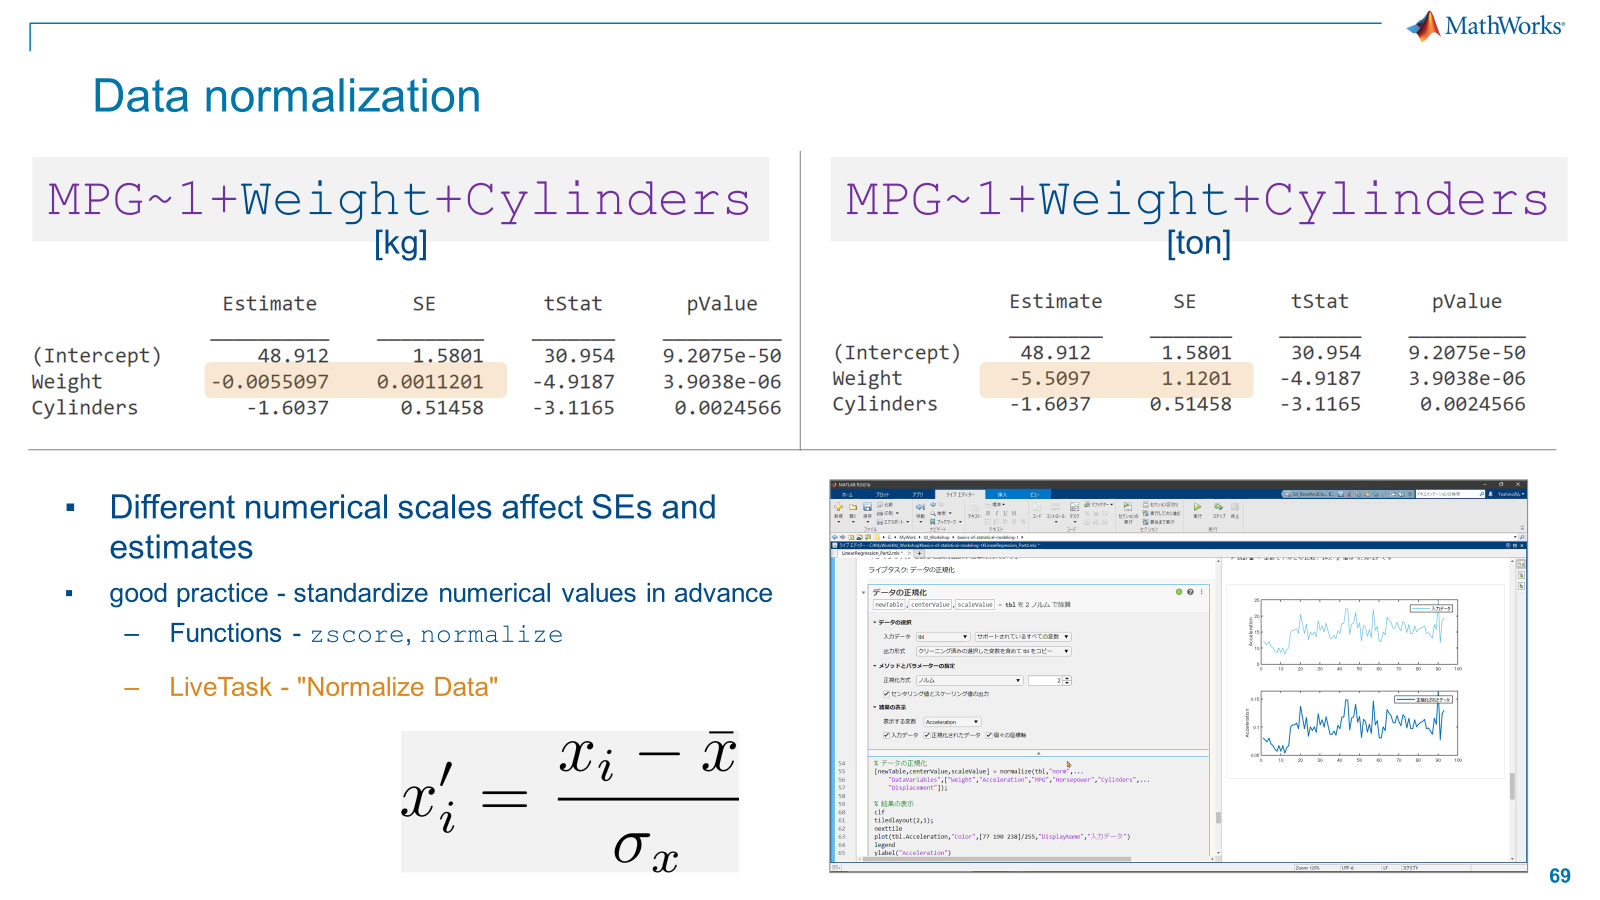

A: 

"It's obvious, but...this is inconvenient. Directly Comparisons cannot be made between variables.'' 

B: 

``That's right. When building a regression model, ** it is good manners to first standardize each variable in some way **     

A: 

"The first thing you do when you receive the data is to do it. This time, we just did it..." 

** Data standardization **

B: 

"Data There are various ways to standardize, but using the Z-score allows you to create a predictor with a mean of 0 and a standard deviation of 1.'' 


$$z = \frac{x - \mu}{\sigma}$$


% (Note) The argument cannot be of table type.
[tbl_z, mu, sigma] = zscore(tbl{:,1:end-1}); 

B: 

``After standardization, return the data to a table..” 

% Convert the array to table type again
tbl_z = array2table(tbl_z,...
    'VariableNames', tbl.Properties.VariableNames(1:end-1));
tbl_z.Model_Year = tbl.Model_Year; 

B: 

“Live tasks make trial and error easier.” 

Live tasks: Data normalization 

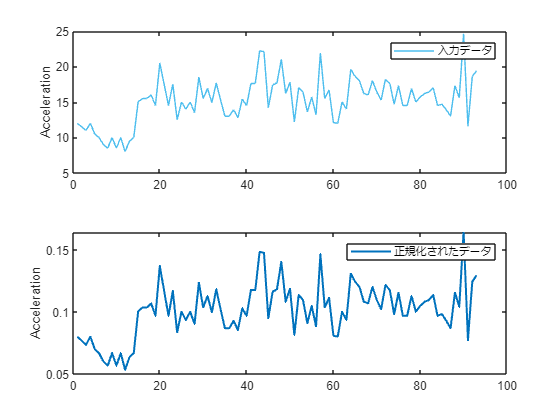

% Data normalization
[newTable,centerValue,scaleValue] = normalize(tbl,"norm",...
    "DataVariables",["Weight","Acceleration","MPG","Horsepower","Cylinders",...
    "Displacement"]);

% Viewing results
clf
tiledlayout(2,1);
nexttile
plot(tbl.Acceleration,"Color",[77 190 238]/255,"DisplayName","入力データ")
legend
ylabel("Acceleration")

nexttile
plot(newTable.Acceleration,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","正規化されたデータ")
legend
ylabel("Acceleration")

figure

##  Summary of points 2 

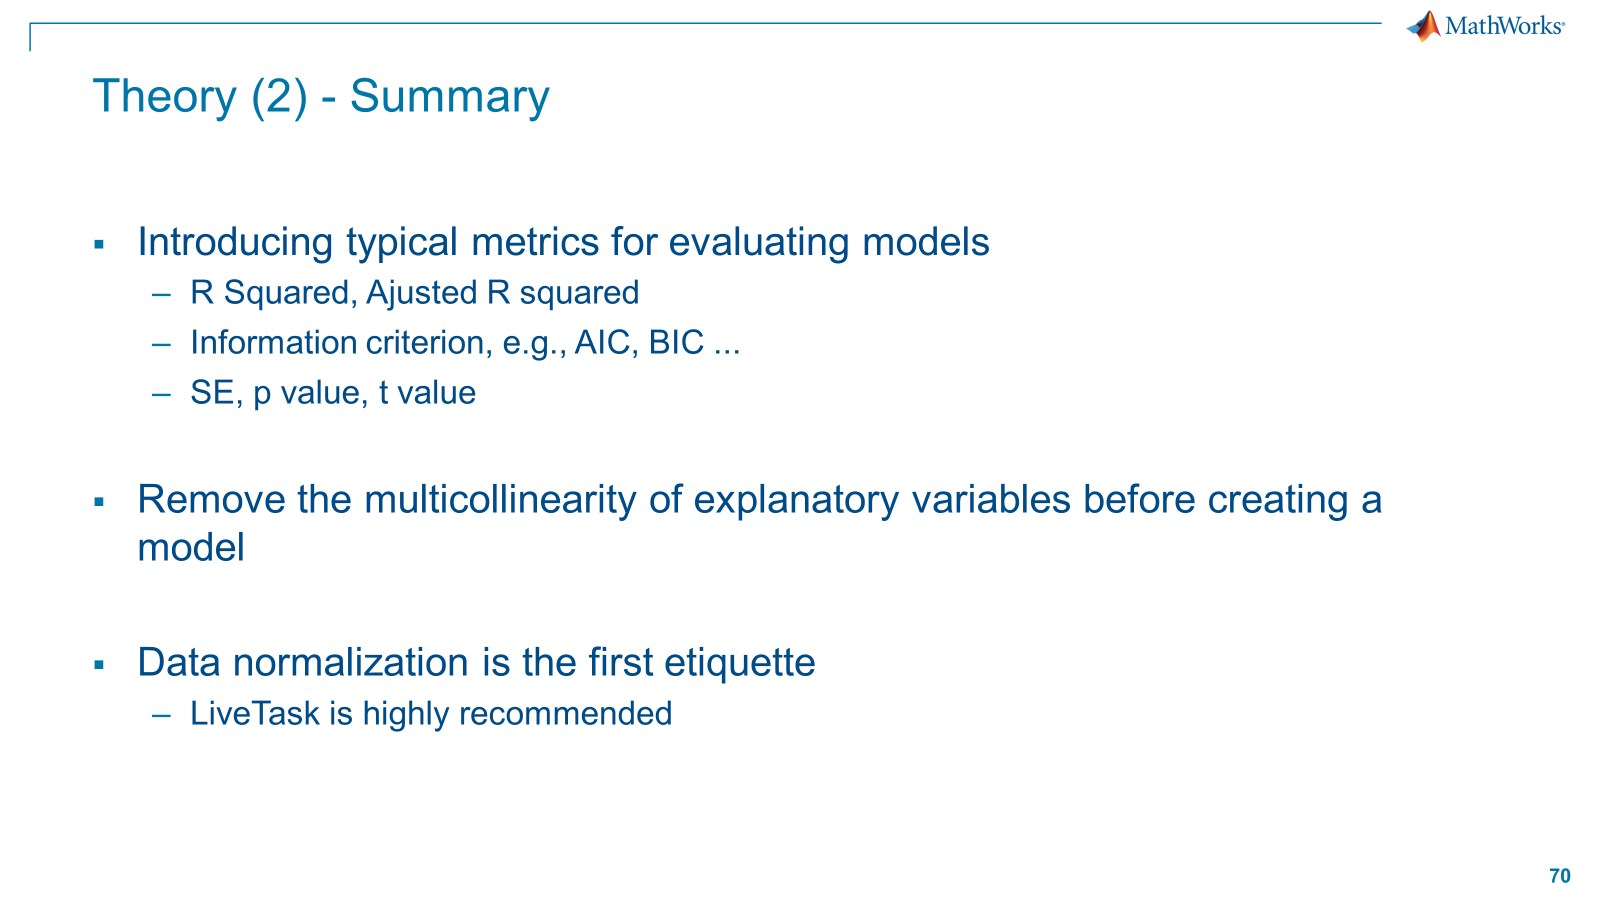

###  Final model 

A: 

“This Now you can create a model using this data!" 

mcol_z = fitlm(tbl_z,'MPG~1+Weight+ Acceleration + Model_Year');
disp(mcol_z); 

Linear regression model:
    MPG ~ 1 + Weight + Acceleration + Model_Year

Estimated Coefficients:
                     Estimate       SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept)      -0.41025    0.073911    -5.5507    2.9677e-07
    Weight            -0.6551    0.045703    -14.334     9.754e-25
    Acceleration       0.0049     0.04563    0.10738       0.91473
    Model_Year_76     0.23718    0.098997     2.3958      0.018701
    Model_Year_82       1.003     0.11039     9.0859    2.7316e-14


Number of observations: 93, Error degrees of freedom: 88
Root Mean Squared Error: 0.359
R-squared: 0.877,  Adjusted R-Squared: 0.871
F-statistic vs. constant model: 156, p-value = 3.99e-39


B: 

"Hmm...I feel like it would be better to remove Acceleration..." 

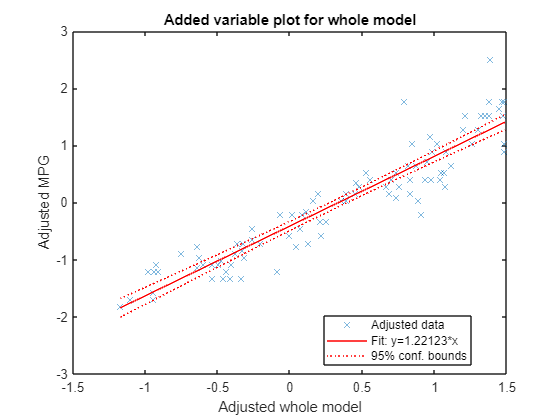

plot(mcol_z); 

There are multiple predictor variables. The plot command behaves the same as plotAdded if: 

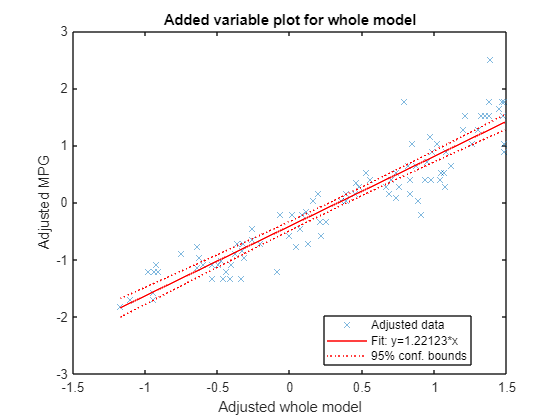

plotAdded(mcol_z);

* Copyright 2022 - 2024 The MathWorks, Inc *